# Representing Data

Chosing the kind of variable to store your data has a big influence on the code you write to analyze the data. This LiveScript  discusses options and gives recommendations how to represent your data, and how this can lead to more structured and reusable code.

## Timeseries data

A large proportion of raw data in Neuroscience are time series, for instance an EEG signal from a scalp electrode,  the presence or absence of a spike on an extracellular electrode, or the voltage recorded by a patch electrode, the position of a rat in a T-maze, or the BOLD signal in an MRI voxel (which is both a time series and a space series). 

While some of these series are vectors, most are higher dimensional. For instance, the EEG data may have multiple channels/electrodes, and the position of the rat has both an X and a Y coordinate. In addition, most experiments use repeated trials to measure the same quantity multiple times.

The most basic variable in Matlab is the array, which can be a scalar, one-dimensional (a vector), two-dimensional (a matrix), or higher-dimensional (ND array). This is the workhorse for data analysis in Matlab - most functions are written to handle arrays, and with arrays you can benefit from vectorization (applying a funciton to each value in a vector, or each column in a matrix).

**If at all possible, you should store (time) series data in an (ND) array. **

For instance, 10 trials of 4 seconds, recording from 256 EEG channels with a 1kHz sampling rates could be stored in an array with size [4000 10 256]. The order of these dimensions matters. In this case, I put the time-per-trial dimension first, followed by the trials, and then the electrodes. 

The default operation of many built-in Matlab functions is to work along the first (row) dimension. Because I anticipate that I will most likely do some analysis on the time dimension first (e.g. find peaks, determine the average), the time-per-trial is along the first dimension of the array. 

Moreover, initially I am going to consider each electrode *separately* in the analysis. That is why the electrode dimension is last. 

With the trial dimension second, functions such as `mean` or `stdev` will then be computed for each trial and each electrode at the same time. This saves a lot of time and makes for cleaner code.

% Load eeg matrix with data [nrTime nrTrials nrE] 
% and time vector with time per trial [nrTime 1]
load ../data/eeg.mat 
[nrTime,nrTrials,nrE]  = size(EEG) %#ok<*ASGLU> 

nrTime = 3200

nrTrials = 50

nrE = 3

from    = 1000;
to      = 2000;
mEEG    = mean(EEG(time>from & time <to,:,:)); % Average over time, for each trial (:) , and each electrode (:) separately
size(mEEG)

ans =      1    50     3


mEEG now has the mean value of the EEG signal in each of the 50 trials, for each of the 3 electrodes. While it can sometimes be useful to keep the dimension that has been reduced to a single entry, often you just want to remove it:

mEEG = squeeze(mEEG)  ;% Remove the singleton dimension (here time)

This has the disadvantage that you have to keep track of which dimension represents which aspect of the data.

If you decide that the arrangement of the data is not ideal for your purposes, you can rearrange the dimensions of the array. For instance, if your primary analysis works by combining signals from electrodes, then it could make sense to have those in the first dimernsion:

EEG = permute(EEG,[3 1 2]); % Rearrange dimensions
[nrE,nrTime,nrTrials]  = size(EEG)

nrE = 3

nrTime = 3200

nrTrials = 50

EEG = permute(EEG,[2 3 1]); % Back to the way it was.

Note that many built-in functions also have input arguments that allow you to specify along which dimension they should work. 

TRIALDIM = 2; % Use a CONST to make the next line more readable
trialAverageEEG = squeeze(mean(EEG,TRIALDIM));
[nrTime,nrE]= size(trialAverageEEG)

nrTime = 3200

nrE = 3

This is a better practice (faster) than permuting the data all the time. In fact, if you find yourself adding `permute` or the apostrophe (`x'`, which is the same as `permute(x,[2 1])`) at multiple places in your code, then you should probably rethink your data representation. *Fix it at the start of the analysis, and few if any permutes will be needed*. 

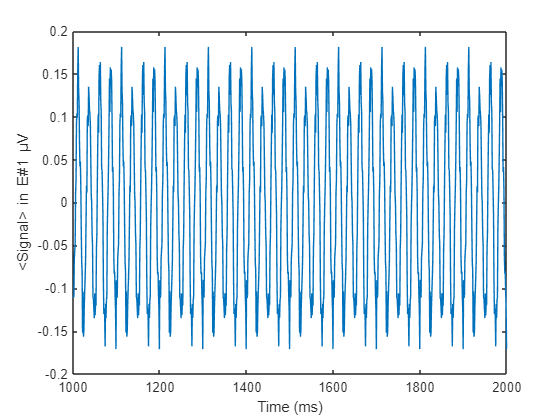

showTime = time> from & time <to;
showE  =1;
plot(time(showTime), trialAverageEEG(showTime,showE));
xlabel 'Time (ms)'
ylabel (['<Signal> in E#' num2str(showE) ' \muV'])

If you collect the same data for a range of subjects, then it makes a lot of sense to simply add each subject as a fourth dimension to this array. That way, your analysis is automaticaly applied to each trial, electrode, and subject. 

### Time series of different observables

Does this mean that you should just include all time series data collected across all experiments in one big array? No. I would only ever store time series together (i.e. in the same array) that have the same units. So EEG from different electrodes yes, but don't add a dimension to also store the pupil size data or skin conductance that you recorded at the same time. Those physcially different quantities belong in a separate array. The mean reason for this is that it will rarely make sense to apply the same algorithm to quantities with different physical units, hence there is little to gain (but much clarity to lose) from putting such data in the same array. Structs are good ways to keep different data modalities with a common origin (e.g. subject, or day of recording) together. More on that below.

The main limitation to using big arrays is size. For a routine fMRI experiment, you could have 100,000 voxels, each with 180 time points. One subject then generates a about 144 megabytes (1e5*180*8bytes per value). That means there is a limit to how many subjects you could reasonable store in one array. In other words, there is a tradeoff between the rapid execution made possible by storing all time series in one array and the amount of memory it takes to do this. That said, for most modern compute machines memory is unlikely to be the primary bottleneck.

### Time series with different sizes

Sometimes your data may not have the same number of entries for each dimension. For instance, your recording trials can be cut short, when the subject looks away from the screen, and as a conseuqence some trials are only 500 ms long, while the longest ones are 3000 ms. Or, you have some recordings with 32 electrodes, while others have only 30. These kind of data sets are sometimes called ragged arrays. 

You may be tempted to store such data in a cell array -  Matlab's catch-all data type to store data of all kinds and sizes. I do not recommend that. Cell arrays are really a variable type of last resort as most analyses get much more complicated with cell arrays than with regular numeric arrays.

A better way to approach the problem of mismatched sizes is to use NaN (not a number) to fill in the missing data in some of the vectors. For instance, if most of your LFP data have trials with 3000 entries (3000 ms sampled at 1 kHz) but one only had 500, supplement that trial with 2500 NaNs, or, more practically, first determine the longest trial and then supplement all the others. This code shows how: 

% Fake data with unequal sizes (pretend you read this from the data file). 
raggedLfpArray = {rand([3000 1]),rand([3100 1]),rand([257 1])};
nrTrials = numel(raggedLfpArray);
% Find the longest trial
nrPerTrial = cellfun(@numel,raggedLfpArray);
maxTrialLength = max(nrPerTrial);
% Initialize the regular array with NaN. Create enough space for the
% longest trial.
lfp = nan(maxTrialLength,nrTrials);
% Then fill each column of lfp with the available values of the ragged
% array.
for tr = 1:nrTrials
      lfp(1:nrPerTrial(tr),tr) = raggedLfpArray{tr};
end


This code would be placed somewhere in your  data import routine. The rest of your analysis code never has to worry about the ragged arrays and can just work on the regular lfp matrix with NaNs indicating the missing values. An imagesc plot visualizes this; NaN values always get the color corresponding to the lowest value (in a `hot` colormap that is black).

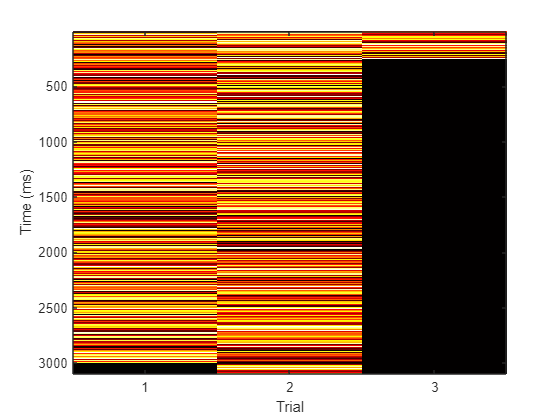

imagesc(1:nrTrials,1:maxTrialLength,lfp)
xlabel 'Trial'
ylabel 'Time (ms)'
ax =gca;
ax.XTick = 1:nrTrials;
colormap hot

As a aside, when visualizing data as images, you want to be able to distinguish real data from missing data. In the plot above this isn't really possible: black represents both missing values (NaN) and values where the LFP happened to be zero. We fix this by first setting the background color of the axis to something that is not in the current colormap. We use blue here. Then we tell `imagesc` to use transparency by setting its so-called alpha value. Where` alpha==0`, the image is completely transparent and the background becomes visible (i.e. blue), where `alpha ==1`, the images is fully opaque and none of the backound is shown.

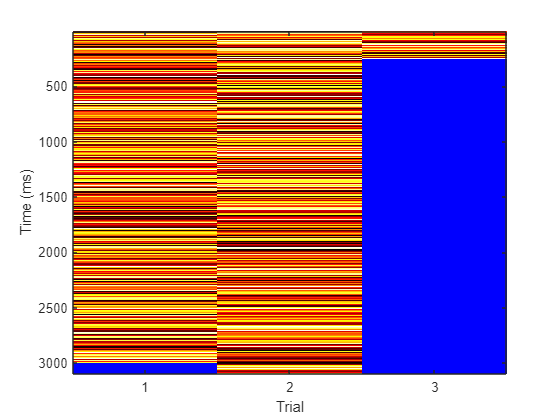

MISSINGVALUECOLOR = [0 0 1];
imagesc(1:nrTrials,1:maxTrialLength,lfp,'AlphaData',~isnan(lfp));
xlabel 'Trial'
ylabel 'Time (ms)'
ax =gca;
ax.XTick = 1:nrTrials;
ax.Color = MISSINGVALUECOLOR; % Set backgrond color
colormap hot

Now the missing values stand out immediately and cannot be confused (visually) with low LFP values. 

## Missing Data

As in the example shown above, your raw data are sometimes incomplete-  a sample missing from an elecrophysiological recording, or a trial without a response in a reaction time experiment. Good recording software writes a clear missing data identifier to the file, although some (older) programs may use a numeric value that is "clearly wrong". This could for instance be a value of -1000 for a reaction time. Read your device's manual carefully to understand its convention. In all of your code you should use `NaN` (not-a-number) to indicate missing values. *Never* use a numeric value as there is the real risk that some bit of analysis code will treat that missing value as if it was a real outcome (for instance, averaging over reaction times and just including that -1000 could give some mysterious results.).  

This also applies to array initialization; if you use a loop to fill some array, you should initialize the array to match the size that it should have at the end of the loop. That is much faster than adding one item at a time. When you initialize an array, never use `zeros`(), always `nan(rows,cols)` - that way if the loop skips one of the entries, a `NaN` will be left in the array; much safer than a zero, which could be taken as real data by a later piece of analysis code. 

#### Working with NaN

One complication when analyzing arrays with NaN values is that some functions don't really know what to do with a NaN. For instance, what is the average of some numbers and one or more NaN?  As the code below shows, Matlab does the sensible/conservative thing, which is to tell you that it does not know (i.e., it returns a NaN). 

mean(lfp)

ans =        NaN    0.4978       NaN


Several built-in functions, however, have a way of dealing with NaN. For instance in this example it would makes sense to simply determine the average over the values that are not NaN:

mean(lfp,"omitnan")

ans =     0.5029    0.4978    0.5108


Not every built-in function has this option, so if a function returns NaN for your dataset you'll have to check the function's help/doc to see whether it can handle NaN. If it cannot, then you will have to remove the NaN-values before passing an array to a function. For instance, you can do this with a logical address:

stay = ~isnan(lfp); % An array with true for the values that are not NaN
mean(lfp(stay) )  % Pass the non-NaN values to the mean function

ans = 0.5007

Note, however, that using such a logical address (`stay) `will change the "shape" of the array:

size(lfp)

ans =         3100           3


size(lfp(stay))

ans =         6357           1


There is no way around that because the values that were not NaN simply do not fit in a regular array, so Matlab converts it to a single column vector. That is why `mean(lfp(stay)) `returned a single value; the grand mean of all the values in `lfp.` To analyze the columns separately you will have to use a for-loop over the columns:

for i=1:size(lfp,2)
    stay = ~isnan(lfp(:,i)); % Non-NaN values in this column
    mean(lfp(stay,i))   % Pick only the non-NaN values and pass those to the mean function
end

ans = 0.5029

ans = 0.4978

ans = 0.5108

This gives the same result as the call to `mean `with `"omitnan". `You should use  such loops only if the analysis function does not have  a built-in way to handle NaN.

### Cell arrays

This missing value approach to ragged arrays comes at the cost of wasting memory (those NaNs need to be stored too and each one takes up 8 bytes). So, in he example above, if one trial was 1 hour long and all others were 500 ms, you'd waste a lot of space. In that specific example, there is probably a good reason to just remove that outlier trial, but there may be other scenarios where you're stuck with a cell array. Vectorization does not work for cell arrays, so

nanmean(lfp)

ans =     0.5029    0.4978    0.5108


calculates the average LFP in each trial, but Matlab does not know how to calculate the mean for each element of a cell array. 

try 
    nanmean(raggedLfpArray)
catch ME
    fprintf(2,'Error: %s',ME.message)
end

Error: Invalid data type. First argument must be numeric or logical.

The cellfun function can help in these cases. It applies the function specificied as the first input argument to each of the elements of the cell array specified as the second argument:

cellfun(@nanmean,raggedLfpArray)

ans =     0.5029    0.4978    0.5108


Using `cellfun` is a way around the limitations of cell arrays, and it beats writing explicit loops over all the elements in a cell array, but it is less readable and it is slower than the regular vectorized calculations that are only possible with numeric arrays. 

## Images

Many imaging devices store data in an integer format. For instance, `uint8`, which stands for unsigned integer with 8 bits. In this format, each pixel has a value between 0 and 255 (=2^8-1). For an image on a common monitor you need three such values per pixel, one for each of the colors red, green, and blue. This representation is quite limited as it only allows 256 shades each of red, green, and blue (limited, yet enough for all the images you see on a screen). Images that contain more detail may use `uint16`, which can use values between 0 and 65535 (=2^16-1) in each pixel.

Matlab has builtin arrays that can store such images; this is convenient mainly to save memory. If you stored the same values in a regular array, they'd take up much more space (8 times as much for a `uint8` as Matlab uses 8 bytes, so 64 bits to store regular, floating point, numbers). The memory saving, however, comes at a price as many regular mathematical operations are not defined for `uint8` or `uint16`.

m = 1:10;
u = uint8(2)

u = uint8
2

try 
    m./u
catch me
    fprintf(2,['Error: ' me.message])
end

Error: Integers can only be combined with integers of the same class, or scalar doubles.

Apparently you cannot devide 1:10 by 2 if that 2 is an integer. It gets worse, though:

m = uint8(m)

m = 1×10 uint8 row vector
    1    2    3    4    5    6    7    8    9   10


m./u

ans = 1×10 uint8 row vector
   1   1   2   2   3   3   4   4   5   5


Division by an uint8 2 is not what you may expect it to be. Even addition can be a problem if the resulting number is outside the range of the data type:

u = uint8(200)

u = uint8
200

u+u

ans = uint8
255

Ouch. It should be clear that, unless you have a very limited amount of memory available, your analysis code will be a lot simpler if you simply transform any image data into an array that uses regular floating point numbers with double precision (the Matlab standard). This requires 8 times the amount of memory:

   whos m

  Name      Size            Bytes  Class    Attributes

  m         1x10               10  uint8              



   m =double(m); % Convert to regular array with type double
   whos m

  Name      Size            Bytes  Class     Attributes

  m         1x10               80  double              



If that causes out of memory problems, you will have to use the integer data types and carefully check your code for limitations of that data type. Given the unexpected results of addition and division shown above, that is not a trivial task. 

## Spike Timing Data

Spike timing is typically recorded with millisecond precision. For a 1 hour recording, that is 3.6 million samples which could be 1 (spike) or 0 (no spike). Storing this naively would require 3.6e6*8 bytes ~ 30 MB. (In Matlab, storing a number as a so-called double, takes up 8 bytes). Not that much, but most of those values would be zero (no spike). Sparse arrays are made for this situation; they assume that all values that are not specified are zero, thus saving a lot of storage space in cases like this.

recordingDuration= 3.6e6;
tSpike = randi(recordingDuration); % Generate 1 spike at a random time in one hour.
spikeTrain = zeros(recordingDuration,1);
spikeTrain(tSpike) =1;
whos spikeTrain

  Name                  Size               Bytes  Class     Attributes

  spikeTrain      3600000x1             28800000  double              



This spikeTrain takes up 28.8MB.

sparseSpikeTrain = sparse(tSpike,1,1,recordingDuration,1); % See help sparse
whos sparseSpikeTrain   

  Name                        Size            Bytes  Class     Attributes

  sparseSpikeTrain      3600000x1                32  double    sparse    



This sparse matrix only takes up 32 Bytes and yet these two matrices are identical.

all(spikeTrain==sparseSpikeTrain)

ans = sparse logical
   (1,1)      1


 With modern compute machines memory is rarely a limiting factor, but for spike timing data, the sparse format can really help to reduce storage needs, and some calculations even go faster with sparse arrays (operation such as `find`, for instance).

The nice thing is that, apart from when you define the variable, you don't have to know that the variable is sparse. All of MATLAB's built-in arithmetic, logical and indexing operations can be applied to sparse matrices, or to mixtures of sparse and full matrices.

## Mixed data

An experiment often consists of multiple kinds of observables ; LFPs and spikes, MRI and skin conductance, EEG and pupilsize. It is recommended to keep such data together. But as discussed above, it is not a good practice to store such data together in one array (the fact that they have different physical units is a giveaway). 

In addition, each experiment has a date and time associated with it, a subject number, maybe a version number, or the person who ran the experiment.  This too can be useful to keep together as it may affect which kind of analysis you want to run, or even to exclude certain data from analysis ("Subject 10 fell asleep halfway through...").

In Matlab, you can use a `struct` to store such disparate data that nevertheless belong together. Here is some code that generates fake data, in real life, each field of the struct would be defined based on something read from a datafile. 

nrTrials = 10;  % Fake data for 10 trials
nrTime   = 1000; % lasting 1000 ms each.
clear neuron
neuron.recordingDate        = '07-12-2015'; 
neuron.animalID             = 152;
neuron.neuronID             = 1;
neuron.experiment           = 'Orientation Tuning';
neuron.experimentVersion    = 2;
neuron.spikes               = rand([nrTime nrTrials])>0.9 % Generating random spike array

neuron = struct with fields:
        recordingDate: '07-12-2015'
             animalID: 152
             neuronID: 1
           experiment: 'Orientation Tuning'
    experimentVersion: 2
               spikes: [1000×10 logical]


Think of the neuron struct as a database that has all the data on that neuron. The fields of the struct still follow the same recommendations as before; use arrays to store data if at all possible.  A recording with multiple neurons is stored in struct array - a vector of structs. 

neuron(2) = neuron(1); % Copy for convenience
neuron(2).neuronID = 175; % This is a different neuron 
neuron(2).animalID = 5; % From a different animal
neuron(2).spikes = rand([nrTime nrTrials])>0.9; % With different spikes

For an experiment with 100 neurons, the neuron struct would have size [100 1]. To analyze one specific neuron you'd pass one element of that struct array to your analysis function  (e.g.` result = myAnalysis(neuron(10)`) . But what if you want to analyze interactions between neurons? In the current data representation, each neuron's spiking data is stored in a separate `struct` (even though those structs are all in the same `struct` array). This is fine if you want to analyze them separately, but not so good if you want to analyze them together. 

There is a simple way to join information from elements of a `struct` array. We know that the .`spikes` field is 2 dimensional, so to combine spikes data from multiple neurons, we concatenate (`cat`) the individual .`spikes` fields in the 3rd dimension: 

NEURONDIM =3;
allSpikes = cat(NEURONDIM, neuron.spikes); % neuron.spikes evaluates to a comma separated list. Hence it is equivalent to allSpikes = cat(NEURONDIM, neuron(1).spikes,neuron(2).spikes,neuron(3).spikes,...)
[nrTime,nrTrials,nrNeurons] =size(allSpikes)

nrTime = 1000

nrTrials = 10

nrNeurons = 2

From this point onward, you can just analyze the `allSpikes` array, which has a copy of the spiking data of all of the neurons in the `neuron` struct.

You can also use concatenation to select items from your array. For instance, you may just want to analyze neurons from one animal.

allAnimalID = [neuron.animalID]; % Create a vector of all animal IDs in the struct array  ( [ x,y ]  is short for cat(1,x,y))
subset = neuron(allAnimalID == 152); % Pick only those that belong to the animal with the ID 152

In this example, we chose neurons as the level of organization for the struct. Whether this is the best choice depends on the analyses you plan to do. If your main focus is on comparing activity of neurons recorded in the same experiment, then the experiment level may be a better choice. In that case I would setup the following data structure (and include observables that are defined at the experiment not the neuron level, such as the animal's pupil size). 

nrNeurons  = 100;
expt.recordingDate        = '07-12-2015'; 
expt.animalID             = 152;
expt.exptID               = 1; % This is the ID of the experiment
expt.neuronID             = 1:nrNeurons;  % Each page in .spikes corresponds to one neuron. This vector contains their IDs.
expt.experiment           = 'Orientation Tuning';
expt.experimentVersion    = 2;
expt.spikes               = rand([nrTime nrTrials nrNeurons])>0.9; % Generating random spike array for all neurons in the experiment.
expt.pupilSize            = rand([nrTime nrTrials]);% Fake pupil data
expt

expt = struct with fields:
        recordingDate: '07-12-2015'
             animalID: 152
               exptID: 1
             neuronID: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
           experiment: 'Orientation Tuning'
    experimentVersion: 2
               spikes: [1000×10×100 logical]
            pupilSize: [1000×10 double]


Now the `expt.spikes `array is analogous to the `allSpikes` array that we created earlier; the data for each neuron are in the pages (3rd dimension) of this array. If you want to analyze just one neuron you can still pick just that neurons data from `expt.spikes`. 

The choice of level depends on what kind of analysis you're likely to do. At the start of a new project, you should think ahead, and try to determine the level that is appropriate. That said, the code above also shows that you're not locked in by your choices. With `cat`() it is easy to move one level up (from the neuron level to the experiment level, for instance), and by selecting elements of an ND array you can go a level down:

expt.spikes(:,:,expt.neuronID==12) ;% Pick the spike data that correspond to neuronID 12

### Pipelines

In my experience, using experiments as the core organizing struct for raw data is most useful. With 'experiment' I mean one recording, typically lasting a few minutes to hours on a specific date, with a single defined experimental paradigm, and a single subject. The reason for this is that, usually, your first analysis steps (including preprocessing) apply to the data in one such experiment. Of course, a subject may run multiple experiments in a single session and sometimes you may want to compare data from one experiment with that from another (e.g. resting state fMRI (experiment 1) with task fMRI( experiment 2), or orientation tuning (experiment 1) with orientation discrimination (experiment 2)).  There is nothing preventing you from doing that and combining information from separate experiment structs of the same or even different subjects. Your data representation does not determine what is possible, only what is easy and what is (somewhat) harder to do. 

You should think of your analysis as a pipeline. Each step creates a new data representation that is passed to the next step. For instance, a preprocessing step could use an experiment-level struct to do quality control and then create a new struct (with a different format) that has the cleaned data needed in the next step. Think of EEG data where some electrodes had a high impedance and bad signal. Your pipeline could take the raw data, use an artifact detection algorithm, and then create a new struct that only containst the cleaned channels. Your next step in the pipeline can then assume that all electrodes have good quality. Isolatng specific analysis steps in separate stages of a pipeline is useful as it allows you to reuse code (the same artifact removal can be used in many projects) and it makes it easier to compare or update different algorithms. If, for instance, you find a new artifact detection algorithm, you can incorporate it into the artifact removal step of your pipeline, rerun the entire pipeline and compare the results. This kind of structure (modularity) really is essential to coding for the long term.

Many steps of a pipeline can benefit from using structs to keep related information together. At the early stages of the pipeline those structs will contain fields with relatively raw data, typically stored in ND arrays, but as you progress in the pipeline, the data are reduced more and more to averages, indices of performance, or other abstract measures that are the output of your data analysis algorithms. With each step in the pipeline the values represent more abstract concepts and (usually) are lower dimensional (e.g. an average removes one dimension). Once your analayis pipeline reaches its endpoint the `table` data type becomes most useful as it provides nice ways to visualize summary results, and performing statistical analysis. 

## Tables

Tables were introduced in Matlab in 2013. These data types are **not **meant for the number crunching that you do with arrays, but they are an excellent choice to represent summary results and as the basis for statistical analysis using mixed models (more on this later). Tables in Matlab are similar to a spreadsheet, there are rows and columns (both can have names), and a table can contain a mixture of numbers, text, and other data types. You can add or remove columns and rows, extract subsets,add meta data describing the properties of the table and much more. 

For an extensive walk-through explaining the various options for working with tables, run this on the Matlab command line: `openExample 'CreateAndWorkWithTableExample.mlx' `and then work your way through the LiveScript.

If you have "raw" data in a spreadsheet format (e.g. MS Excel) , then tables can be a great way to get these data into Matlab to perform analysis or visualziation. 

Although I use tables typically only to store summary results (and to do statistical analyses using LMM), you can perform other analyses on elements of a table. Just as with cell arrays, this is not as straightforward as with numerical arrays, but it can be done. For instance, the `varfun` function applies a function (that you specify) to each of the columns in the table, or to a subset of columns (that you specify). This is similar to the cellfun function used with cell arrays. 

% Define a table with reaction times before and after a drug injection
reactionTimes = table([712;205;350;282;257],[230;120;108;320;401],'VariableNames',{'Before','After'})

reactionTimes = 5×2 table
    Before    After
    ______    _____

     712       230 
     205       120 
     350       108 
     282       320 
     257       401 


% Determine the mean per column
meanRT = varfun(@mean,reactionTimes)

meanRT = 1×2 table
    mean_Before    mean_After
    ___________    __________

       361.2         235.8   


The `rowfun` function is similar; it applies a function to each row in a table. With `SeparateInputs` set to `false` you can pass a row as a vector to the specified function (by default the elements of a row are passed to the function as a comma separated list).

pairwiseDifferenceRT = rowfun(@diff,reactionTimes,'SeparateInputs',false)  % 

pairwiseDifferenceRT = 5×1 table
    Var1
    ____

    -482
     -85
    -242
      38
     144


Other useful funtions are `findgroups `and `groupsummary` which find certain rows in the table that belong together (e.g. they correspond to the same subject or the same gender) and then perform an analysis (a function that you specify) for each of those groups. This is similar to a Pivot Table in Excel. 

% Create a table
Gender = ["male";"female";"female";"male";"male"];
Age = [38;43;38;40;49];
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
T = table(Gender,Age,Height,Weight)

T = 5×4 table
     Gender     Age    Height    Weight
    ________    ___    ______    ______

    "male"      38       71       176  
    "female"    43       69       163  
    "female"    38       64       131  
    "male"      40       67       133  
    "male"      49       64       119  


Compute the counts of males and females by specifying `'Gender'` as the grouping variable.

G = groupsummary(T,'Gender') %#ok<*NASGU> 

G = 2×2 table
     Gender     GroupCount
    ________    __________

    "female"        2     
    "male"          3     


Compute the mean age, height, and weight of females and males separately.

G = groupsummary(T,'Gender',@mean)

G = 2×5 table
     Gender     GroupCount    fun1_Age    fun1_Height    fun1_Weight
    ________    __________    ________    ___________    ___________

    "female"        2            40.5         66.5            147   
    "male"          3          42.333       67.333         142.67   


Still grouping by gender, compute the median height only. 

G = groupsummary(T,'Gender',@median,'Height')

G = 2×3 table
     Gender     GroupCount    fun1_Height
    ________    __________    ___________

    "female"        2            66.5    
    "male"          3              67    


### Tables and Struct Arrays

In principle, anything that can be stored in a struct array can also be stored in a table. Matlab provides built-in functions to convert between the two. And in this LiveScript Matlab even visualizes these different types the same way (as a table...):

s = table2struct(G)

s = 2×1 struct array with fields:
    Gender
    GroupCount
    fun1_Height


Table type variables are particularlly useful as your analysis gets closer to the final resutls, First of all, because tables are similar to a spreadsheet they are easier to read on the command line. This is helpful for interpretable numbers such as the number of subjects, or the mean reaction time, but much less so for raw data (the recorded voltage). Second, there is a function called `writetable `that creates a comma separated text file of values from a table. That can be useful to share sumary data with other researchers (who may not use Matlab but can read a comma separated file), or to inject your results into a pipeline that uses such text files as its input (e.g. tsv files in BIDS MRI pipelines). Cnoversely, the `readtable `function can read comma separated files, or even Excel formats into a table.

## Summary

- The keep it together mantra: things that belong together should be stored together.

- Time series (or any series of related numbers) with values that have the same units (e.g. mV, kg, [Ca 2+]) should be stored in regular ND arrays. If the number of dimensions is high, code clarity is improved by defining constants that name each of these dimensions.  (e,g,  `TIMEDIM=1;TRIALDIM    =2; ELECTRODEDIM=3`;). Note that using  `squeeze `can change dimensions, so make sure to update these definitions in your code where needed).

- Missing values should always be represented by NaN.

- Cell arrays should be avoided if possible.

- structs or tables are a good way to group disparate data /observables that belong to the same experiment (or session, or subject)

- images should be stored in regular ND arrays, using the double data type.

- Tables are a great way to store summary results for statistical analysis.